alpha = 1 + mod(273,3)

alpha = 1

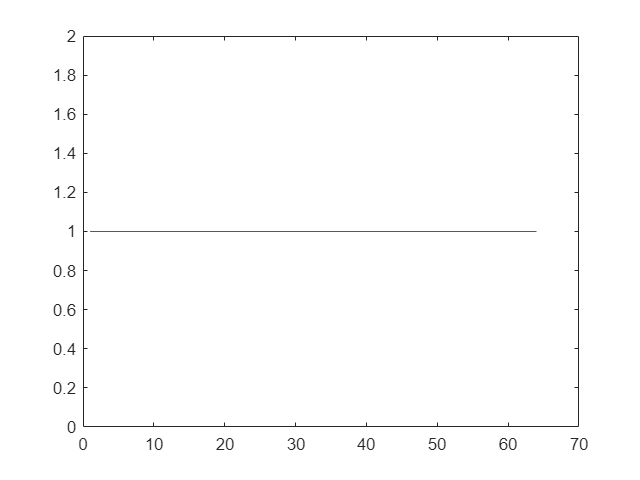

N = 64;            % Window length

plot(rectwin(N));

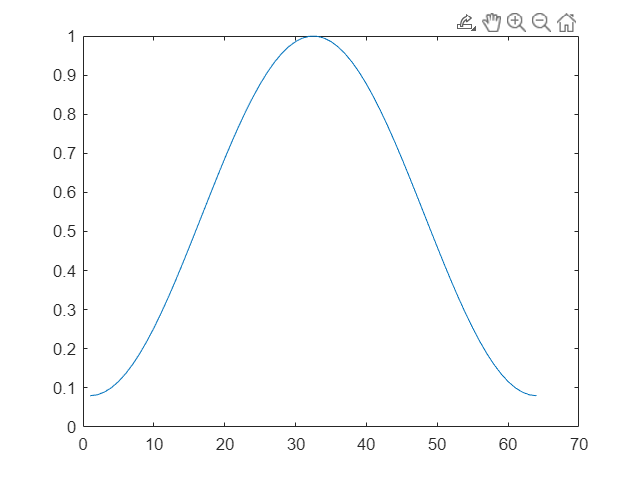

plot(hamming(N));

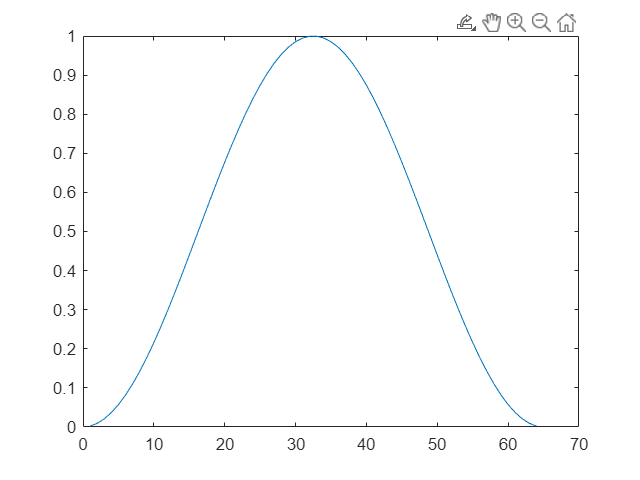

plot(hanning(N));

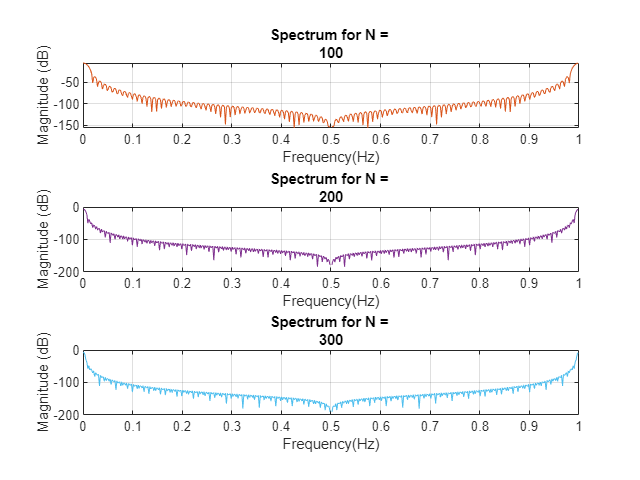

%Specify the parameters
N_values=[100,200,300];
DFT_size=512;
fs=1000;        %Sampling rate
F=100;          %Signal Frequency
time=(0:(DFT_size-1))/fs;
for i=1:length(N_values)
    window=hanning(N_values(i));
    windowed_signal=window.*sign(1:N_values(i));

    %Compute the DFT
    signal_DFT=fft(windowed_signal, DFT_size);
    normalized=abs(signal_DFT)/N_values(i);

    %Make the frequency axis
    f=(0:(DFT_size-1))/DFT_size;

    %Plot the spectrum
    subplot(3,1,i);
    plot(f,20*log10(normalized));
    grid on;
    title(["Spectrum for N = " num2str(N_values(i))]);
    xlabel("Frequency(Hz)");
    ylabel("Magnitude (dB)");
end

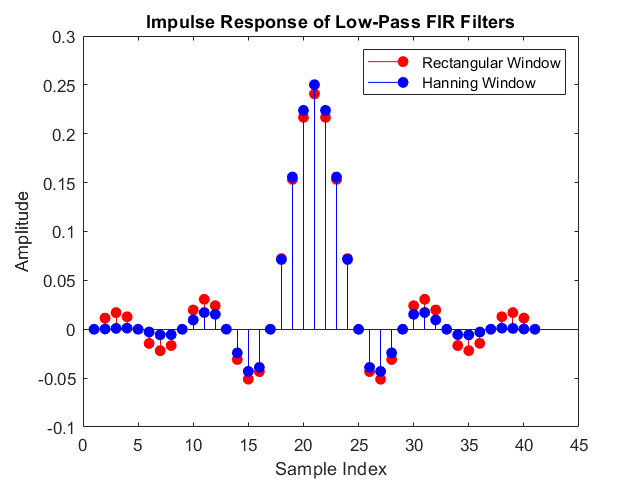

M = 41;
%Calculate the cutoff frequency in radians per sample
omega_c = pi / (alpha + 1);

% Design the FIR filter using rectangular window
h_rectangular = fir1(M - 1, omega_c / (2 * pi), 'low', rectwin(M));

% Design the FIR filter using Blackman window
h_hanning = fir1(M - 1, omega_c / (2 * pi), 'low', hanning(M));

% Impulse response plots
figure;
stem(h_rectangular, 'r', 'filled');
hold on;
stem(h_hanning, 'b', 'filled');
hold off;
legend('Rectangular Window', 'Hanning Window');
xlabel('Sample Index');
ylabel('Amplitude');
title('Impulse Response of Low-Pass FIR Filters');

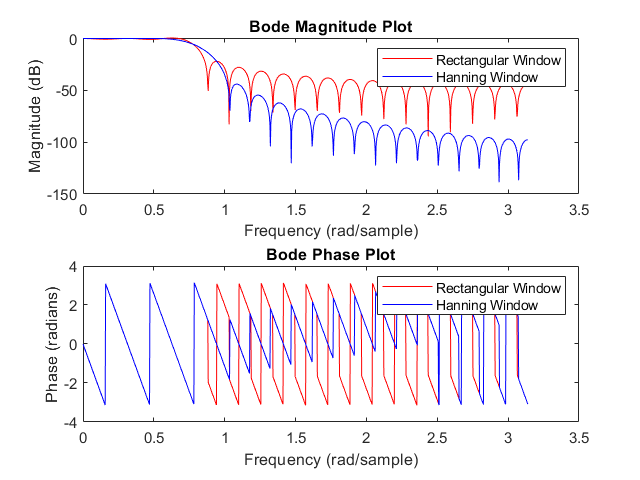


% Frequency response of the filters
[H_rectangular, w] = freqz(h_rectangular, 1, 1024);
[H_hanning, ~] = freqz(h_hanning, 1, 1024);

% Calculate magnitude and phase of the frequency response
magnitude_rectangular = 20 * log10(abs(H_rectangular));
magnitude_blackman = 20 * log10(abs(H_hanning));
phase_rectangular = angle(H_rectangular);
phase_blackman = angle(H_blackman);

% Bode plots
figure;
subplot(2, 1, 1);
plot(w, magnitude_rectangular, 'r');
hold on;
plot(w, magnitude_blackman, 'b');
hold off;
title('Bode Magnitude Plot');
xlabel('Frequency (rad/sample)');
ylabel('Magnitude (dB)');
legend('Rectangular Window', 'Hanning Window');

subplot(2, 1, 2);
plot(w, phase_rectangular, 'r');
hold on;
plot(w, phase_blackman, 'b');
hold off;
title('Bode Phase Plot');
xlabel('Frequency (rad/sample)');
ylabel('Phase (radians)');
legend('Rectangular Window', 'Hanning Window');

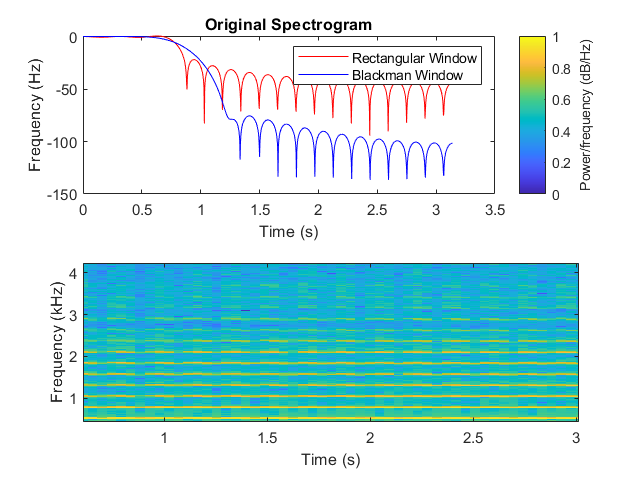

% Load the audio file
[y, fs] = audioread('instru1.wav');

% Plot the spectrogram of the original signal
windowSize = 1024; % You can adjust this window size
overlap = 512;     % You can adjust the overlap
spectrogram(y, windowSize, overlap, [], fs, 'yaxis');
title('Original Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

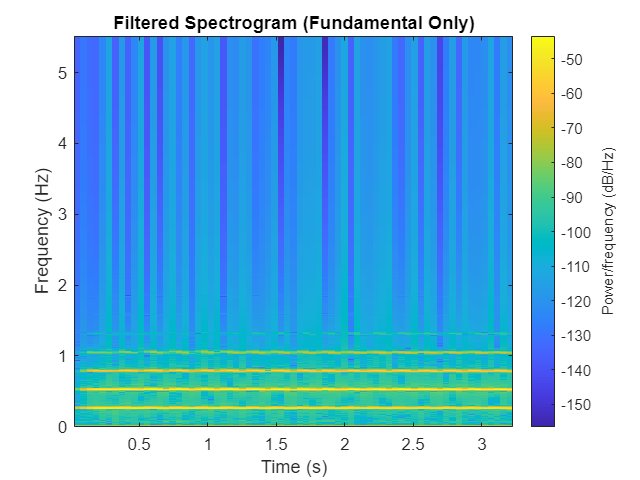


figure;

cutoffFrequency = 1000; 
filterOrder = 51;       


window = hanning(filterOrder + 1);
filterCoeff = fir1(filterOrder, cutoffFrequency / (fs/2), window);

% Apply the FIR filter to the audio signal
filteredSignal = filter(filterCoeff, 1, y);

% Plot the spectrogram of the filtered signal
spectrogram(filteredSignal, windowSize, overlap, [], fs, 'yaxis');
title('Filtered Spectrogram (Fundamental Only)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');


figure;
% Write the filtered audio to a .wav file
audiowrite('filtered_audio.wav', filteredSignal, fs);